# Individual Assignment

Before starting I set the random number generator to a known state, in order to get the same results when running the code. 

rng('default');

First I import the data as a Table. I use 'import data'. Home > Import Data > datset Individual Assignment > as table > import selection

## Task 1.

t1 = datsetIndividualAssignment;
summary(t1);

Variables:

    datetime: 3202×1 datetime

        Values:

            Min       01-Jan-2010 00:00:00
            Median    21-Jul-2014 12:00:00
            Max       31-Dec-2018 00:00:00

    T_mu: 3202×1 double

        Values:

            Min       -22.675 
            Median        6.4 
            Max        26.146 

    Po_mu: 3202×1 double

        Values:

            Min         729.5 
            Median     759.21 
            Max        790.42 

    P_mu: 3202×1 double

        Values:

            Min        729.85 
            Median     759.54 
            Max        790.81 

    Ff_mu: 3202×1 double

        Values:

            Min        1.1667 
            Median      3.375 
            Max        10.792 

    Tn_mu: 3202×1 double

        Values:

            Min        -26.2  
            Median       4.7  
            Max        23.65  

    Tx_mu

1) 

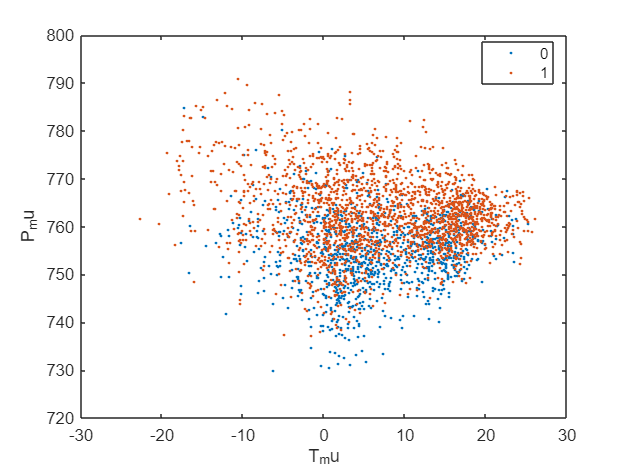

gscatter(t1.T_mu, t1.P_mu, t1.OBSERVED)
xlabel('T_mu')
ylabel('P_mu')

2)

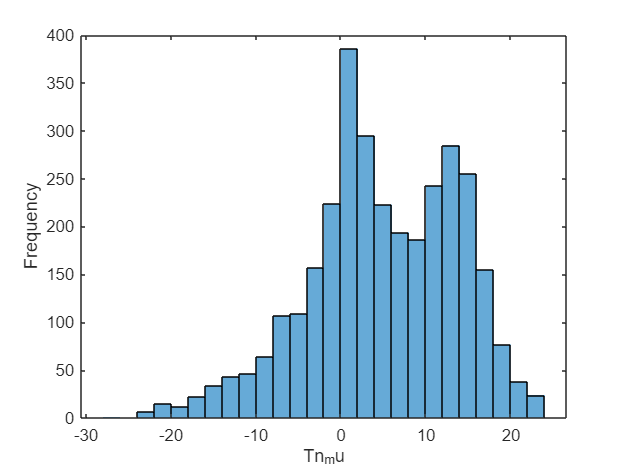

histogram(t1.Tn_mu)
xlabel('Tn_mu')
ylabel('Frequency')

3)

Obs1 = t1.OBSERVED

Obs1 =      1
     1
     0
     0
     0
     0
     0
     1
     1
     1


[grpG,ObsVals] = findgroups(Obs1)

grpG =      2
     2
     1
     1
     1
     1
     1
     2
     2
     2


ObsVals =      0
     1


maxTd_mu=splitapply(@max,t1.Td_mu,grpG)

maxTd_mu =    20.3000
   21.4625


Let's visualize the results

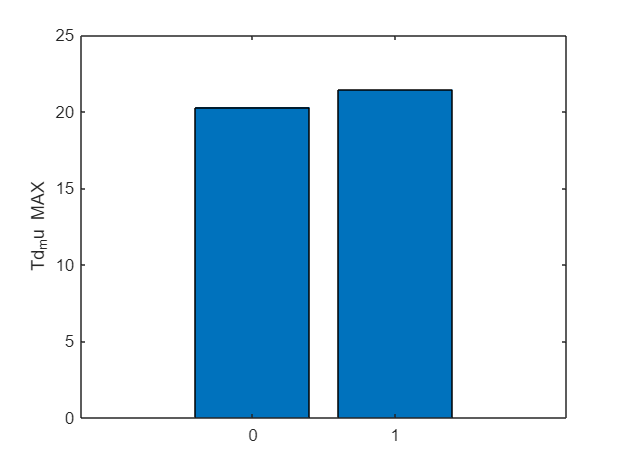

bar(maxTd_mu)
xticklabels(ObsVals)
ylabel("Td_mu MAX")

4)

meanP_var=splitapply(@mean,t1.P_var,grpG)

meanP_var =     5.4376
    3.0735


Let's visualize the results

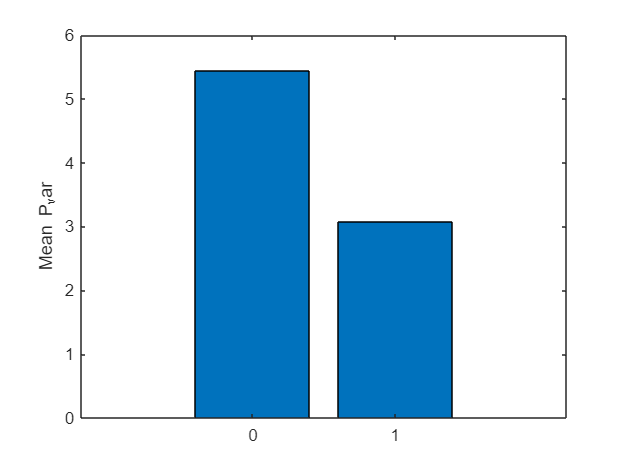

bar(meanP_var)
xticklabels(ObsVals)
ylabel("Mean P_var")

5)

t1.datetime

ans = 3202×1 datetime array
   01-Jan-2010
   02-Jan-2010
   03-Jan-2010
   04-Jan-2010
   05-Jan-2010
   06-Jan-2010
   07-Jan-2010
   08-Jan-2010
   09-Jan-2010
   10-Jan-2010
   11-Jan-2010
   12-Jan-2010
   13-Jan-2010
   14-Jan-2010
   15-Jan-2010
   16-Jan-2010
   17-Jan-2010
   18-Jan-2010
   19-Jan-2010
   20-Jan-2010
   21-Jan-2010
   22-Jan-2010
   23-Jan-2010
   24-Jan-2010
   25-Jan-2010
   26-Jan-2010
   27-Jan-2010
   28-Jan-2010
   29-Jan-2010
   31-Jan-2010


% parse dates
[y,m,d] = datevec(t1.datetime);
Tdate = table(y,m,d,'VariableName',{'year','month','day'});

% Variable table1 is now our new table that contains all the original
% variables except datetime. Instead now we have three new columns: day,
% month & year
table1 = table(Tdate.day, Tdate.month, Tdate.year, t1.T_mu, t1.Po_mu,t1.P_mu,t1.Ff_mu,t1.Tn_mu,t1.Tx_mu,t1.W_mu,t1.Td_mu,t1.T_var,t1.Po_var,t1.P_var,t1.Ff_var,t1.Tn_var,t1.Tx_var,t1.W_var,t1.Td_var,t1.OBSERVED,t1.U_mu,'VariableName',{'day','month','year','T_mu','Po_mu','P_mu','Ff_mu','Tn_mu','Tx_mu','W_mu','Td_mu','T_var','Po_var','P_var','Ff_var','Tn_var','Tx_var','W_var','Td_var','OBSERVED','U_mu'});


6)

The response variables: the binary variable OBSERVED and the continuous variable U_mu

The rest of data are predictors (the predictors matrix X).

Y1 = table1.OBSERVED;
Y2 = table1.U_mu;
X = [table1.day, table1.month,table1.year, table1.T_mu, table1.Po_mu,table1.P_mu,table1.Ff_mu,table1.Tn_mu,table1.Tx_mu,table1.W_mu,table1.Td_mu,table1.T_var,table1.Po_var,table1.P_var,table1.Ff_var,table1.Tn_var,table1.Tx_var,table1.W_var,table1.Td_var];

rng('default');

## Task 2.

principal component analysis (PCA)

#### 1)

[coeff,score,latent,~,explained]= pca(X)

coeff =     0.0008    0.0040    0.0311    0.0054    0.3886    0.9166    0.0868    0.0026    0.0124   -0.0047    0.0009    0.0074   -0.0050   -0.0035    0.0010    0.0027    0.0008    0.0003    0.0001
    0.0006    0.0622   -0.0176   -0.0005    0.0226    0.0009   -0.0872    0.0116    0.0766    0.9689    0.0447    0.1276   -0.1266   -0.0793   -0.0474    0.0049    0.0057    0.0002   -0.0002
   -0.0049    0.0027   -0.0097   -0.0119    0.0092   -0.0035   -0.0149    0.0198   -0.0414   -0.0493    0.9733    0.1805    0.1160    0.0290    0.0112   -0.0233   -0.0090   -0.0011   -0.0000
   -0.0067    0.4922   -0.0039   -0.0323    0.0805   -0.0367   -0.0199   -0.0325    0.0376   -0.0678    0.0244    0.0030   -0.1726   -0.0260    0.0262    0.0129    0.8422    0.0073   -0.0012
   -0.0184   -0.0602    0.5826   -0.2039    0.2581   -0.1102   -0.1865    0.0057    0.0194   -0.0045    0.0005   -0.0195    0.0048    0.0212    0.0084   -0.0028   -0.0034    0.0987    0.7003
   -0.0184   -0.0608    0.5828   -0.2

score =    89.9359  -37.8463   -5.3020    2.6200   -6.3355  -13.6869    4.2009    3.2247    3.2792   -3.2102   -3.7842    1.1755   -0.3372   -0.4919    0.7556    0.2458   -0.6121   -0.0060   -0.0042
  -54.1187  -46.2131    5.6231    5.8283  -17.3942   -7.4039   -2.4967    3.9102   -1.9457   -2.0947   -4.2301   -0.4440   -0.1134   -0.3380   -0.0912   -0.1946   -0.4521    0.0145   -0.0044
  159.7424  -41.7797   18.6296   23.0646   23.1743  -33.1306   91.9323  -91.8175   22.1031    6.5444    2.5900  -10.2265    7.1730   -0.9606    2.6642    3.7738   -0.6651    0.0954   -0.0065
  194.8846  -17.8025   -3.4172    1.1759  -16.8926   -5.8028    1.0790    2.4034   -2.0758   -4.0475   -3.8015    1.8524    1.1270   -0.2324    0.0417   -1.3170    0.8212    0.0121   -0.0121
  -13.7091  -27.0421    1.8401   26.3867    0.2981  -15.3620   34.7208   -5.1013   12.7218   -0.2245   -1.8558   -6.9987    3.8853   -0.6638    0.5631    0.2152   -2.4715   -0.0527    0.0043
   45.3924  -34.8000    2.4902   -4.0

latent = 1.0e+03 *

    8.7921
    0.3137
    0.1606
    0.1207
    0.0788
    0.0762
    0.0589
    0.0333
    0.0134
    0.0106


explained =    90.8774
    3.2430
    1.6603
    1.2473
    0.8146
    0.7873
    0.6092
    0.3443
    0.1388
    0.1090


principal_components = corr(score)

principal_components =     1.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    1.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000    1.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    1.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000  


% Replace upper triangle with NaNs
upper = logical(triu(ones(size(principal_components)),1));
principal_components(upper) = NaN

principal_components =     1.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0000    1.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.0000    0.0000    1.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.0000    0.0000    0.0000    1.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0000    0.0000   -0.0000    0.0000    1.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.0000   -0.0000  

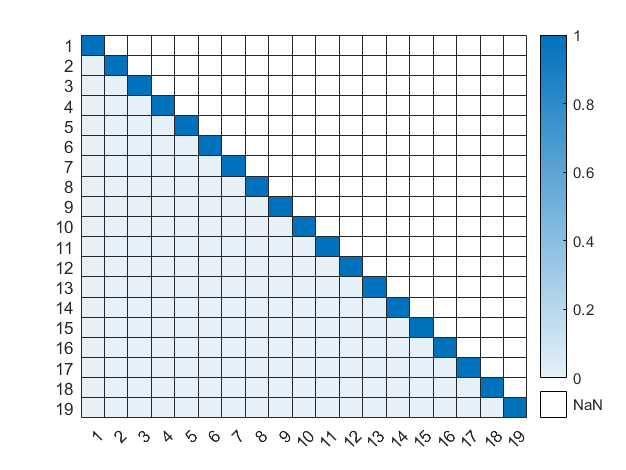

% Plot results
hm = heatmap(principal_components,'MissingDataColor','w');

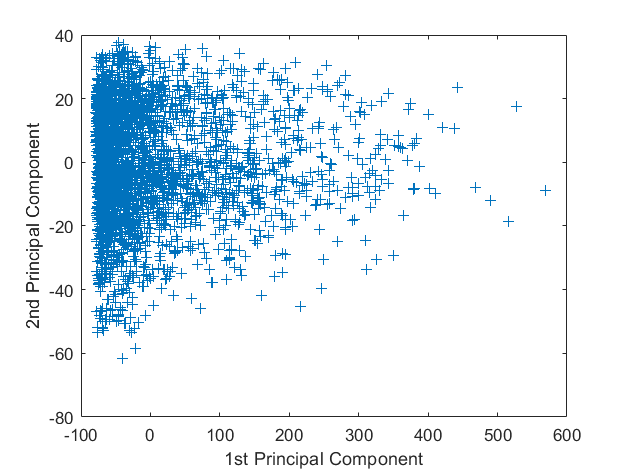


%Create a plot of the first two columns of score
figure()
plot(score(:,1),score(:,2),'+')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')

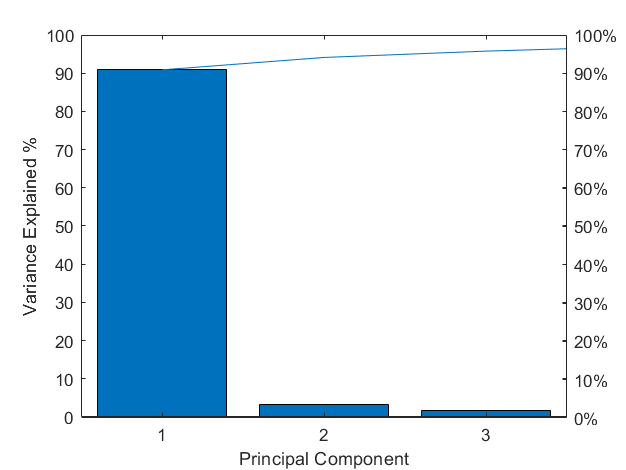


figure()
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained %')

The number of principal components: 2 

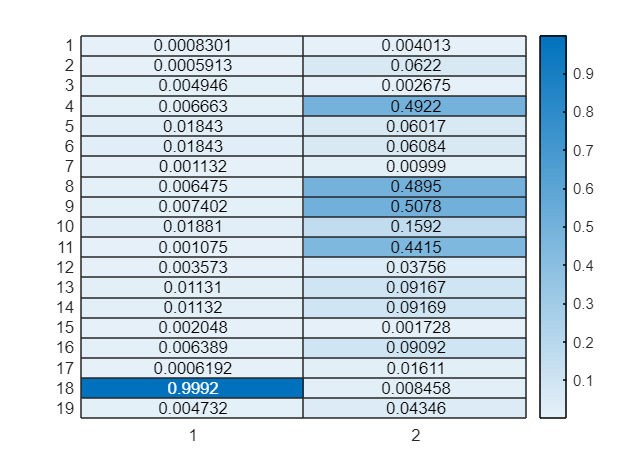

summa = sum(explained(1:2,:)); %  the first 2 components explain over 94% of the total variance

abs(coeff(:,1:2));
heatmap(abs(coeff(:,1:2))) % I can see that variable W_var (row 18) in 1st principal component and variable Tx_mu (row 9) in 2nd principal component contribute the most 


% Project data onto first two principal components
k = 2;
X_reduced = X * coeff(:,1:k) % this is the data that I can use when performing steps 2,3 and 4

X_reduced =   130.1900 -108.0200
  -13.8645 -116.3868
  199.9965 -111.9535
  235.1388  -87.9763
   26.5450  -97.2159
   85.6465 -104.9737
    6.4712 -102.7560
  -17.0801 -116.8043
  -23.0636 -115.9815
  -21.8539 -113.2177


#### 2) K-means and the Squared Euclidean distance

2 clusters: 

[cidx2,cmeans2] = kmeans(X_reduced,2,'display','iter');

  iter	 phase	     num	         sum
     1	     1	    3202	 9.20367e+06
     2	     1	      52	 8.96295e+06
     3	     1	      24	 8.91732e+06
     4	     1	      12	 8.90577e+06
     5	     1	       5	 8.90407e+06
     6	     1	       1	 8.90381e+06
Best total sum of distances = 8.90381e+06


3 clusters:

[cidx3,cmeans3] = kmeans(X_reduced,3,'display','iter');

  iter	 phase	     num	         sum
     1	     1	    3202	 5.79826e+06
     2	     1	      52	 5.38005e+06
     3	     1	      44	 5.23934e+06
     4	     1	      39	 5.16711e+06
     5	     1	      34	 5.11461e+06
     6	     1	      34	 5.05929e+06
     7	     1	      31	 5.03081e+06
     8	     1	      24	 5.00627e+06
     9	     1	      15	 4.99759e+06
    10	     1	      11	 4.99498e+06
    11	     1	       9	 4.99326e+06
    12	     1	       9	  4.9918e+06
    13	     1	       8	 4.99059e+06
    14	     1	       7	 4.98986e+06
    15	     1	       4	 4.98945e+06
    16	     1	       3	 4.98919e+06
    17	     1	       2	 4.98911e+06
    18	     1	       1	 4.98909e+06
Best total sum of distances = 4.98909e+06


4 clusters:

[cidx4,cmeans4] = kmeans(X_reduced,4,'display','iter');

  iter	 phase	     num	         sum
     1	     1	    3202	 3.43956e+06
     2	     1	      62	 3.37346e+06
     3	     1	      46	 3.33662e+06
     4	     1	      43	 3.30896e+06
     5	     1	      34	 3.29613e+06
     6	     1	      27	 3.28639e+06
     7	     1	      20	 3.28225e+06
     8	     1	      15	    3.28e+06
     9	     1	      13	 3.27857e+06
    10	     1	      10	 3.27727e+06
    11	     1	      10	 3.27476e+06
    12	     1	      13	 3.27165e+06
    13	     1	      10	 3.26983e+06
    14	     1	       8	 3.26856e+06
    15	     1	       6	 3.26821e+06
    16	     1	       5	 3.26793e+06
    17	     1	       4	 3.26771e+06
    18	     1	       2	 3.26768e+06
    19	     1	       1	 3.26768e+06
Best total sum of distances = 3.26768e+06


5 clusters:

[cidx5,cmeans5] = kmeans(X_reduced,5, 'display','iter');

  iter	 phase	     num	         sum
     1	     1	    3202	 2.66655e+06
     2	     1	     151	 2.58026e+06
     3	     1	      64	 2.55684e+06
     4	     1	      60	 2.54607e+06
     5	     1	      32	 2.54011e+06
     6	     1	      32	 2.53498e+06
     7	     1	      16	 2.53346e+06
     8	     1	      15	 2.53267e+06
     9	     1	      13	 2.53189e+06
    10	     1	       8	 2.53161e+06
    11	     1	       9	 2.53134e+06
    12	     1	       6	 2.53124e+06
    13	     1	       7	 2.53114e+06
    14	     1	       3	 2.53104e+06
    15	     1	       4	 2.53098e+06
    16	     1	       4	 2.53091e+06
    17	     1	       1	 2.53088e+06
    18	     1	       1	 2.53087e+06
    19	     1	       2	 2.53084e+06
    20	     1	       6	 2.53051e+06
    21	     1	       4	 2.53017e+06
    22	     1	       9	 2.52971e+06
    23	     1	       8	 2.52941e+06
    24	     1	       5	 2.52928e+06
    25	     1	       3	 2.52921e+06
    26	     1	       3	 2.52918e+06
    27	     1	       1	 2.52

To asses the quality of the clusters, I use Silhouette method: 

2 clusters: 

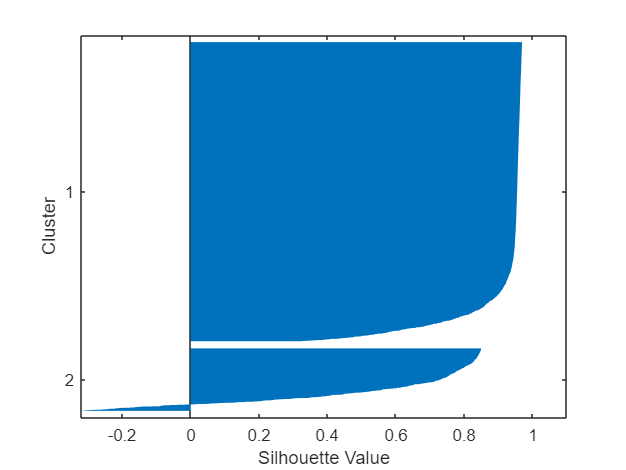

[silh2,hm] = silhouette(X_reduced,cidx2,'sqeuclidean');

mean(silh2)

ans = 0.8583

3 clusters:

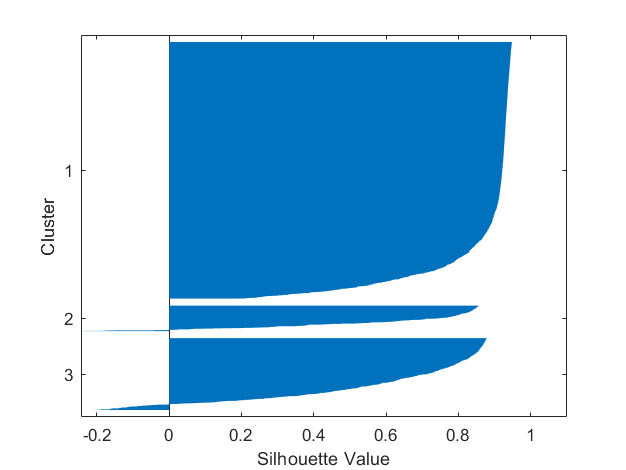

[silh3,hm] = silhouette(X_reduced,cidx3,'sqeuclidean');

mean(silh3)

ans = 0.7915

4 clusters:

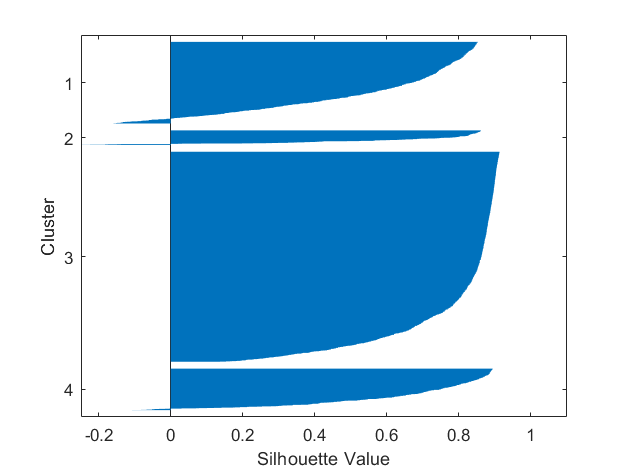

[silh4,hm] = silhouette(X_reduced,cidx4,'sqeuclidean');

mean(silh4)

ans = 0.7145

5 clusters:

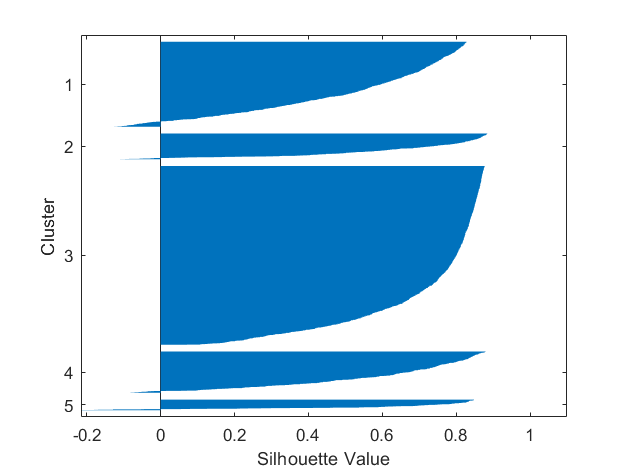

[silh5,hm] = silhouette(X_reduced,cidx5,'sqeuclidean');

mean(silh5)

ans = 0.6461

Automated cluster quality evaluation:

EC = evalclusters(X_reduced,'kmeans','silhouette','klist',[2:5])

EC =   SilhouetteEvaluation with properties:

    NumObservations: 3202
         InspectedK: [2 3 4 5]
    CriterionValues: [0.8583 0.7905 0.7145 0.6600]
           OptimalK: 2


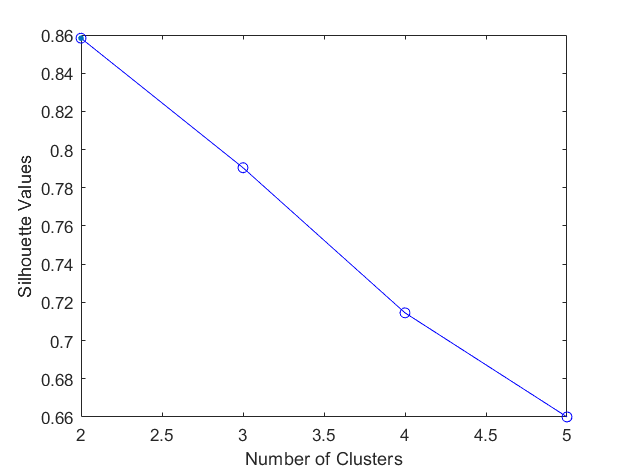

figure;
plot(EC)

Let's create a scatter plot (2D):

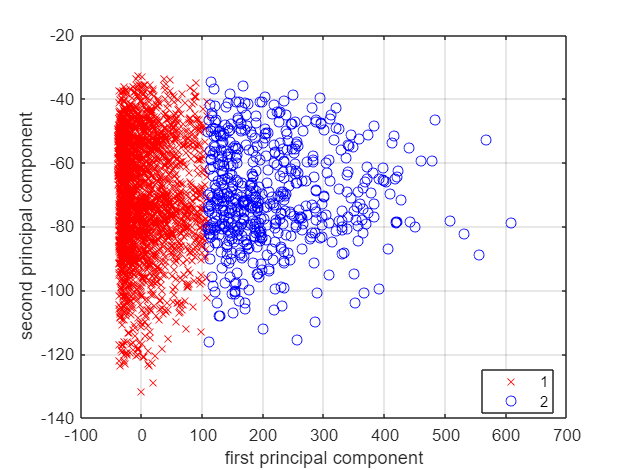

figure;
gscatter(X_reduced(:,1),X_reduced(:,2),EC.OptimalY,'rbg','xod')
xlabel('first principal component');
ylabel('second principal component');
grid on

#### 3) Hierarchical Clustering, the Cosine distance, and linkage “average”

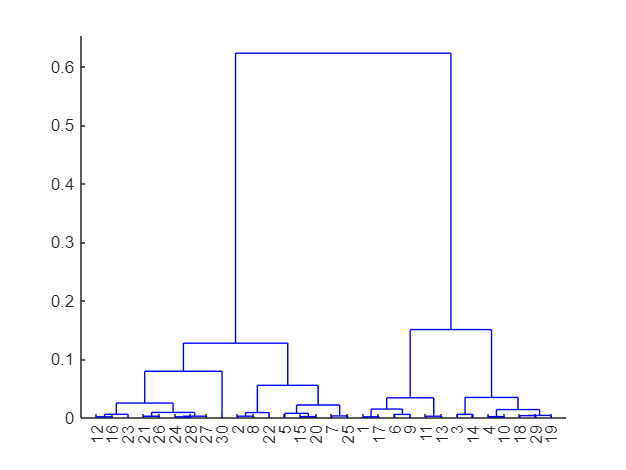

cosDis = pdist(X_reduced,'cosine');
clustTree_Cos = linkage(cosDis,'average');
dendrogram(clustTree_Cos)

From figure, that command *dendrogram(clustTreeCos) *gives, I can see that when cutoff = 0.6 I get two clusters.

Let's visualize the colored clusters in the dendogram:

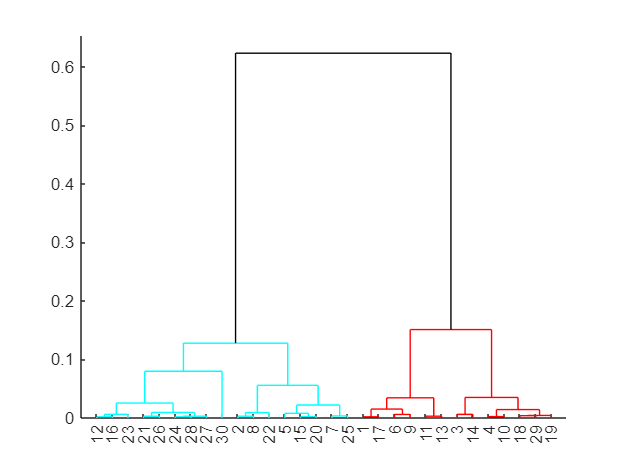

dendrogram(clustTree_Cos,'ColorThreshold',0.6)

I evaluate the clustering result with the help of Silhouette method:

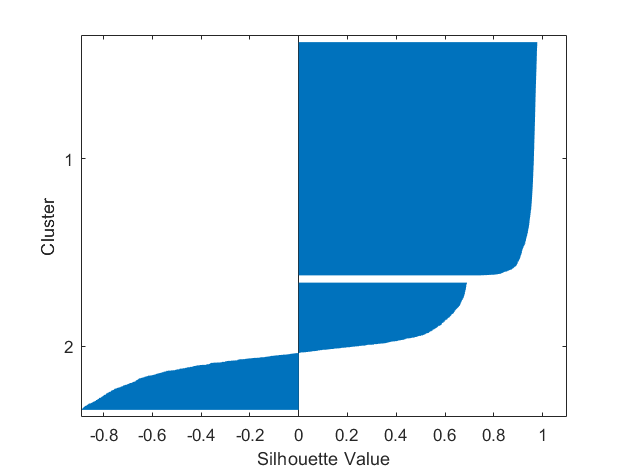

h_cos = cluster(clustTree_Cos,'criterion','distance','cutoff',0.6);
[silhtreecos,hm] = silhouette(X_reduced,h_cos);

mean(silhtreecos);

f = @(X_reduced,k) clusterdata(X_reduced,'linkage','average','Distance','cosine','maxclust',k);
Evaluate = evalclusters(X_reduced,f,'silhouette','klist',[2:6])

Evaluate =   SilhouetteEvaluation with properties:

    NumObservations: 3202
         InspectedK: [2 3 4 5 6]
    CriterionValues: [0.6282 0.5669 0.4003 0.2342 0.1600]
           OptimalK: 2


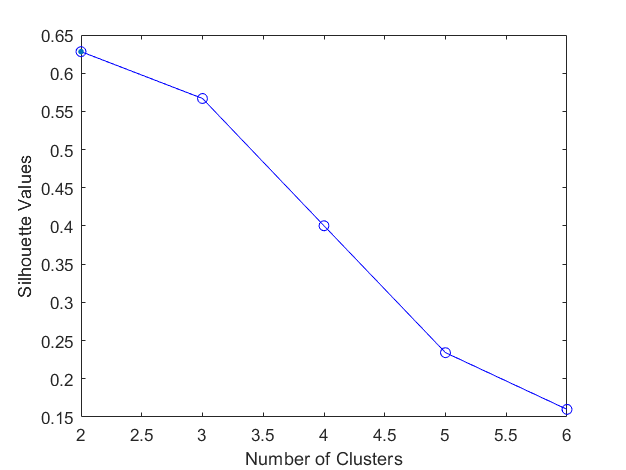


figure;
plot(Evaluate)

Based on Silhouette method I would evaluate solution best as possible I can get. If there would be more clusters, the results would be worse. 

#### 4) GMM (Gaussian Mixture Model)

First I specify 3 GMM components (clusters) and 1000 maximum iterations for the EM algorithm.

k = 3; % clusters
options = statset('MaxIter',1000);
gm = fitgmdist(X_reduced,k,'Options',options);

P = posterior(gm,X_reduced); % first column: cluster one, second column: cluster two, third column: cluster three
idx = cluster(gm,X_reduced);
threshold = [0.59 0.3 0.01]; % testing the tresholds
idxall3 = find(P(:,1)>threshold(1) & P(:,2)>threshold(2) & P(:,3)>threshold(3));
numInAll3 = numel(idxall3);


probability = P(8,:) % probabilities of 8th observation: the first, the second, and the third cluster

probability =     0.0120    0.3927    0.5954


rng('default');

## Task 3

**1) Dividing the dataset**

%Y1 = table1.OBSERVED;
%Y2 = table1.U_mu;
%X = [table1.day, table1.month,table1.year, table1.T_mu, table1.Po_mu,table1.P_mu,table1.Ff_mu,table1.Tn_mu,table1.Tx_mu,table1.W_mu,table1.Td_mu,table1.T_var,table1.Po_var,table1.P_var,table1.Ff_var,table1.Tn_var,table1.Tx_var,table1.W_var,table1.Td_var];

First let's divide the data to training data and test data:

cv1 = cvpartition(length(X),'holdout',0.30);
cv2 = cvpartition(length(Y2),'holdout',0.30);

Training set

Xtrain = X(training(cv1),:);
Y2train = Y2(training(cv2),:);

Test set

Xtest = X(test(cv1),:);
Y2test = Y2(test(cv2),:);

**2) Let's train a linear regression model using all the available predictors in X. I use training data (Xtrain & Y2train).**

mdl=fitlm(Xtrain,Y2train,'linear')

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)        798.09       185.94      4.2923    1.8444e-05
    x1              -0.031732     0.026091     -1.2162       0.22402
    x2                0.99984     0.073298      13.641    9.5726e-41
    x3               -0.38995     0.091273     -4.2723    2.0161e-05
    x4                -1.0627      0.50817     -2.0913      0.036615
    x5                -9.3252       10.064    -0.92663       0.35422
    x6               

**3)  Let's divide training data: 20% validation data, 80% training data**

cv3 = cvpartition(length(Xtrain),'holdout',0.20);
cv4 = cvpartition(length(Y2train),'holdout',0.20);

Training set number 2

Xtrain2 = Xtrain(training(cv3),:);
Y2train_2 = Y2train(training(cv4),:);

Validation set

Xval = Xtrain(test(cv3),:);
Yval = Y2train(test(cv4),:);

**4) Let's train and validate two Ridge models with Lambda equal to 2 and 5 respectively.**

First lambda = 2

Lambda = 2;
b = ridge(Y2train_2, Xtrain2,Lambda,0);
ypred_ridge_lambda1 = b(1) + Xval*b(2:end);

Let's calculate the error:

MSE1 = immse(Yval,ypred_ridge_lambda1)

MSE1 = 164.1926

Now lambda = 5

Lambda = 5;
b2 = ridge(Y2train_2, Xtrain2,Lambda,0);
ypred_ridge_lambda2 = b2(1) + Xval*b2(2:end);

Let's calculate the error:

MSE2 = immse(Yval,ypred_ridge_lambda2)

MSE2 = 163.4270

I choose the lamda that has the smallest MSE-value. Based on the results MSE1 and MSE2 give, I choose MSE2 (lambda = 5).

Now I can train the model with this lambda for the whole training dataset.

best_lambda_R = 5;
best_model_R=ridge(Y2train, Xtrain,best_lambda_R,0)

best_model_R =   821.7094
   -0.0304
    1.0113
   -0.3989
   -0.6609
    0.0412
    0.0378
    0.8086
   -0.2609
   -0.4053


Let's test the best model on the test data.

test_R= best_model_R(1) + Xtest*best_model_R(2:end)

test_R =    75.9037
   78.8537
   81.9857
   84.1191
   83.1126
   83.5519
   82.2988
   81.1958
   80.5710
   81.6592


MSE_R= (mean((test_R - Y2test) .^ 2))

MSE_R = 150.0839

For the best ridge model, the test MSE is 150.0839

**5) Let's train and validate two Lasso models with Lambda equal to 0.01 and 0.2 respectively.**

I start with Lambda = 0.01

[B,fitInfo] = lasso(Xtrain2, Y2train_2,'Lambda',0.01);

ypred_lasso_lambda001 = fitInfo.Intercept + Xval*B;
MSE3 = (immse(Yval,ypred_lasso_lambda001))

MSE3 = 163.9939

Next I do the same with Lambda = 0.2

[B2,fitInfo2] = lasso(Xtrain2, Y2train_2,'Lambda',0.2);

ypred_lasso_lambda02 = fitInfo2.Intercept + Xval*B2;
MSE4 = (immse(Yval,ypred_lasso_lambda02))

MSE4 = 156.6408

Based on the MSE3 and MSE4 results, I will choose lambda = 0.2

Let's run the model on the test data with lambda = 0.2

best_lambda_L = 0.2;
[Bfinal,fitInfofinal] = lasso(Xtrain, Y2train,'Lambda',best_lambda_L);

Let's test the best model on the test data.

test_L= fitInfofinal.Intercept + Xtest*Bfinal;
MSE_L= (immse(Y2test,test_L))

MSE_L = 144.9656

For the best Lasso model, the test MSE is 144.9656

**6) Principal Component Regression (PCR)**

I create a loop to speed up the process

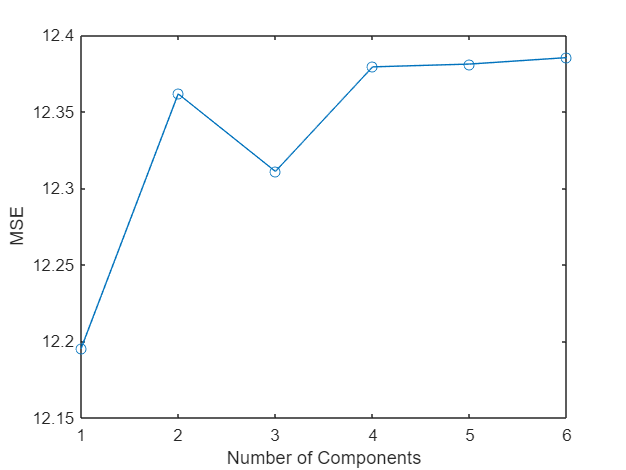

% First I define range of components to test (=6)
max_components = 6; % Maximum number of components to validate
mse = zeros(max_components,1); % Root mean squared error

% Let's loop the components
for i = 1:max_components
    [coeff_PCR,score_PCR,~,~,explained_PCR,mu_PCR] = pca(Xtrain2);
    Xtrain_PCA = score_PCR(:,1:i);
    PCR_model = fitlm(Xtrain_PCA,Y2train_2);
    scoreVal=(Xval-mu_PCR)*coeff_PCR(:,1:i);
    Yvalidation_predicted=predict(PCR_model,scoreVal);
    mse(i) = sqrt(immse(Yval,Yvalidation_predicted));
end

% Let's plot the results
plot(1:max_components,mse,'-o')
xlabel('Number of Components')
ylabel('MSE')

Now I have the results from the loop. Based on the the results it obtains, I will use 4 components in my final PCA.

[coeff_final,scoreTrain_final,~,~,explained_final,mu_final] = pca(Xtrain);% first I apply PCA to the whole traing dataset
scoreTraincomp_final = scoreTrain_final(:,1:4);% select four components

final_model_PCR=fitlm(scoreTraincomp_final,Y2train);
score_Test4_comps=(Xtest-mu_final)*coeff_final(:,1:4); %prepare test data considering four components
y_predicted_test_PCR=predict(final_model_PCR,score_Test4_comps);
MSE_PCR= (immse(Y2test,y_predicted_test_PCR))

MSE_PCR = 129.7068

MSE for the final PCR is 129.7068

**7) RMSE evaluation**

% RMSE for first model (linear regression) we see from variable mdl = 10.7
RMSE1 = sqrt(MSE_R) % RMSE Ridge

RMSE1 = 12.2509

RMSE2 = sqrt(MSE_L) % RMSE Lasso

RMSE2 = 12.0402

RMSE3 = sqrt(MSE_PCR) % RMSE PCR

RMSE3 = 11.3889

From these results I can see that the best performance shows linear regression model (from point 2).

Lasso and ridge give very close values. Linear regression gives by far the lowest value while the RMSE of PCR falls between these models.

Lasso regression removes components from the model completely at a given point. PCA and Ridge regression, on the other hand, reduce the importance of components without removing them completely. This makes it difficult to judge which model would work best.

 If all variables had roughly the same effect, Lasso regression would turn out to be the worst option. This is because the number of explanatory variables would probably have to be reduced, even if not justified, when using Lasso regression. On the other hand, if certain variables had more influence over others, Lasso Regression could therefore be a potential model.

PCA makes convenient use of large numbers of variables, as it is able to reduce them considerably. The challenge with PCA, however, is that it is difficult to explicitly express the nature of the data in hindsight.

 Ridge keeps every variable in the model, so it can be seen as a benefit. On the other hand, this can pose computational challenges while keeping the dimensions the same.

rng('default');

## Task 4

**1) Splitting the data**

part1 = cvpartition(length(X),'holdout',0.30);
part2 = cvpartition(length(Y1),'holdout',0.30);

Training set

Xtrain = X(training(part1),:);
Y1train = Y1(training(part2),:);

Test set

Xtest = X(test(part1),:);
Y1test = Y1(test(part2),:);

**2) Applying Kold cross-validation (K=4) **

n1 = length(Xtrain);
n2 = length(Y1train);

K4_1 = cvpartition(n1,'KFold', 4);
K4_2 = cvpartition(n2,'KFold', 4);

**3) Training and cross-validating a Lasso Logistic Regression model**

[B,FitInfo] = lassoglm(Xtrain,Y1train,'binomial','CV',K4_2,'NumLambda',30);
B;

% How many features do you get if you use Lambda1SE ?
idxIndex1SE = FitInfo.Index1SE;
B0_1SE = FitInfo.Intercept(idxIndex1SE);%intercept at the Lambda1SE
B_lasso_1SE=B(:,idxIndex1SE)

B_lasso_1SE =          0
   -0.0228
    0.0524
         0
         0
         0
         0
         0
         0
         0



coef_lambda1SE = [B0_1SE; B_lasso_1SE]

coef_lambda1SE =  -104.8226
         0
   -0.0228
    0.0524
         0
         0
         0
         0
         0
         0



features_lambda1SE = FitInfo.DF(idxIndex1SE) % number of features if I  use Lambda1SE

features_lambda1SE = 2


% Number of features if I use Lambda1SE: 2


%How many features do you get if you use LambdaMinDev?

idxIndexMinDev = FitInfo.IndexMinDeviance;
B0_MinDev = FitInfo.Intercept(idxIndexMinDev);%intercept at the LambdaMinDev
B_lasso_MinDev=B(:,idxIndexMinDev)

B_lasso_MinDev =          0
   -0.0415
    0.0720
         0
         0
         0
         0
         0
    0.0057
         0



coefficients_LMD = [B0_MinDev; B_lasso_MinDev]

coefficients_LMD =  -144.1247
         0
   -0.0415
    0.0720
         0
         0
         0
         0
         0
    0.0057



features_lambdaMinDev = FitInfo.DF(idxIndexMinDev) % number of features if I  use LambdaMinDev

features_lambdaMinDev = 3


% Number of features if I use LambdaMinDev: 3


Plots: 

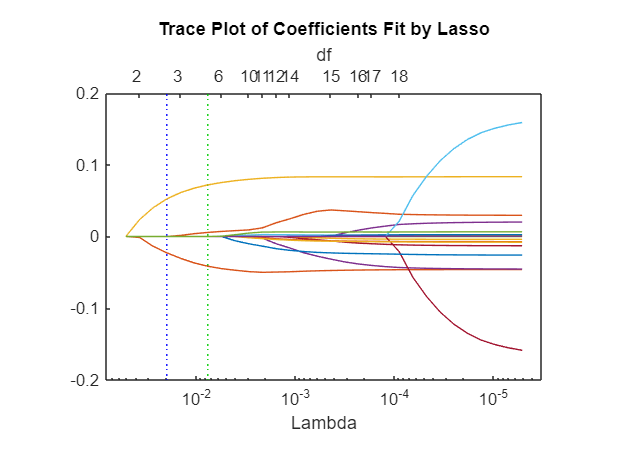

% Plot the number of predictors in the fitted lasso regularization as a function of Lambda, using a logarithmic x-axis.
lassoPlot(B,FitInfo,'PlotType','Lambda','XScale','log');

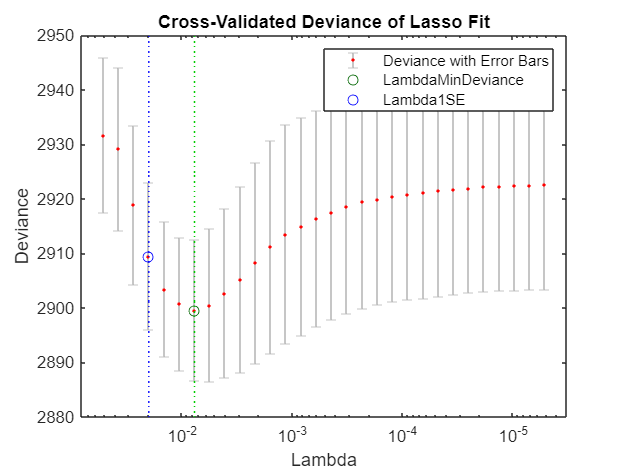


% Plot the cross-validated Deviance as a function of Lambda
lassoPlot(B,FitInfo,'plottype','CV'); 
legend('show') 

Discuss the difference between the two values of Lambda and how they affect the predictors matrix:

The two values of Lambda, Lambda1SE and LambdaMinDev, are selected using different criteria. Lambda1SE corresponds to the smallest value of Lambda that gives a model within one standard error of the minimum cross-validated deviance. This value of Lambda gives a simpler model that is less likely to overfit the data. LambdaMinDev corresponds to the value of Lambda that gives the minimum cross-validated deviance, which corresponds to the best possible model fit to the training data.

The choice of Lambda affects the number of predictors that are included in the model. A smaller value of Lambda will include more predictors, while a larger value of Lambda will include fewer predictors. The value of Lambda1SE typically gives a simpler model with fewer predictors than LambdaMinDev, since it corresponds to a less complex model that is still close to the best possible fit.

In the context of lasso regression, the predictors matrix is affected by the choice of Lambda because it determines which predictors are included in the model and which are excluded. A smaller value of Lambda will lead to more predictors being included, while a larger value of Lambda will lead to fewer predictors being included. The choice of Lambda should be made based on a trade-off between model complexity and goodness of fit to the data.

Re-train the whole training data using Lambda1SE:

**4) Training and cross-validating SVM models**

part1 = cvpartition(length(X),'holdout',0.30);
part2 = cvpartition(length(Y1),'holdout',0.30);

Training set

Xtrain = X(training(part1),:);
Y1train = Y1(training(part2),:);

Test set

Xtest = X(test(part1),:);
Y1test = Y1(test(part2),:);


 Kfold cross validation:

n1 = length(Xtrain);
n2 = length(Y1train);

K4_1 = cvpartition(n1,'KFold', 4);
K4_2 = cvpartition(n2,'KFold', 4);


% SVM classifier with RBF kernel
SVMModel1 = fitcsvm(Xtrain, Y1train, 'KernelFunction', 'RBF', 'KernelScale', 'auto', 'Standardize', true, 'CVPartition', K4_1);
CVSVMModel1 = kfoldLoss(SVMModel1);

CVSV_accuracy_1 = 1 - CVSVMModel1 

CVSV_accuracy_1 = 0.6155


% SVM classifier with polynomial kernel
SVMModel2 = fitcsvm(Xtrain, Y1train, 'KernelFunction', 'polynomial', 'Standardize', true, 'CVPartition', K4_1);
CVSVMModel2 = kfoldLoss(SVMModel2);

CVSV_accuracy_2 = 1 - CVSVMModel2

CVSV_accuracy_2 = 0.5473


% Get the accuracy of the third fold
loss=kfoldLoss(SVMModel1, 'mode','individual');
accuracy3th = 1-loss;
thirdfoldaccuracy = accuracy3th(3,:) 

thirdfoldaccuracy = 0.6381

Based on cross-validation accuracy, select the best SVM model out of the 2 aforementioned models:

I choose the SVM model that has highest cross validation accuracy (CVSV_accuracy_1 or CVSV_accuracy_2): 

In this case it would be CVSV_accuracy_1. 

% Re-train the whole training data using the parameters of the best selected model.
FinalModel = fitcsvm(Xtrain, Y1train, 'KernelFunction', 'RBF', 'KernelScale', 'auto', 'Standardize', true);

predicitionstotestdata= predict(FinalModel,Xtest);


**5) The classification tree model**

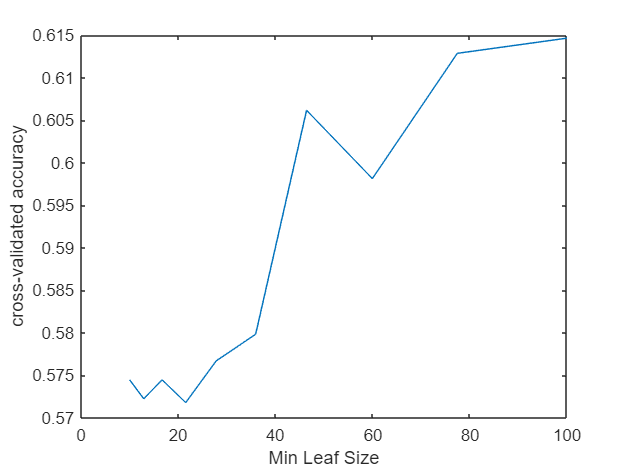

leafs_sizes = logspace(1, 2, 10);
Num = numel(leafs_sizes);
err = zeros(Num,1);
for n=1:Num
    tree_model = fitctree(Xtrain, Y1train, 'CVPartition', K4_1, 'MinLeafSize', leafs_sizes(n));
    accuracy(n) = 1-kfoldLoss(tree_model);

end
plot(leafs_sizes,accuracy);
xlabel('Min Leaf Size');
ylabel('cross-validated accuracy');


% Based on the plot: the best leaf size is at 100

% Let's retrain the whole training data
FMtree =fitctree(Xtrain,Y1train,'MinLeafSize',100);


**6) AUC**

**7) Confusion Matrix**